begin = 1;
ending = 4;
x = linspace(begin, ending, 100);
fun = @(t) sin(t);


Вычисления:

result_l = left_rectangle(x, fun);
result_m = mid_rectangle(x, fun);
result_tr = trapezoid(x, fun);
result_S = Simpson(x, fun);


Альфы:

for n = 10:1:1000
    x_test1 = linspace(begin, ending , n);
    deviat1 = abs(integral(fun, begin, ending) - left_rectangle(x_test1, fun));
    alph1(n) = -log(deviat1)/log(n);
end

for n = 10:1:1000
    x_test2 = linspace(begin, ending ,n);
    deviat2 = abs(integral(fun, begin, ending) - mid_rectangle(x_test2, fun));
    alph2(n) = -log(deviat2)/log(length(x_test2));
end

for n = 10:1:1000
    x_test3 = linspace(begin, ending ,n);
    deviat3 = abs(integral(fun, begin, ending) - trapezoid(x_test3, fun));
    alph3(n) = -log(deviat3)/log(length(x_test3));
end

for n = 10:1:1000
    x_test4 = linspace(begin, ending ,n);
    deviat4 = abs(integral(fun, begin, ending) - Simpson(x_test4, fun));
    alph4(n) = -log(deviat4)/log(length(x_test4));
end


Графики:

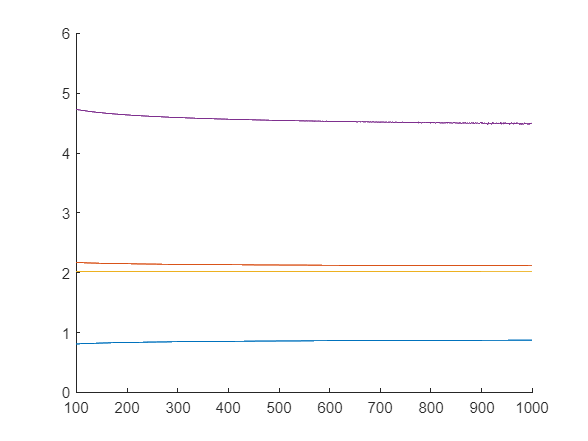

hold on
plot(alph1);
plot(alph2);
plot(alph3);
plot(alph4);
xlim([100 1000])
ylim([0.0 6.0])